    **MANUAL PCA METHOD USING EIGEN VECTORS** 

%import data
data=rand(100,2)

data =     0.8507    0.5590
    0.5606    0.8541
    0.9296    0.3479
    0.6967    0.4460
    0.5828    0.0542
    0.8154    0.1771
    0.8790    0.6628
    0.9889    0.3308
    0.0005    0.8985
    0.8654    0.1182


%standardze the data
x_std = (data - mean(data,1)) ./ std(data,0,1)

x_std =     1.0991    0.3473
    0.1398    1.3314
    1.3599   -0.3569
    0.5898   -0.0295
    0.2133   -1.3362
    0.9823   -0.9264
    1.1926    0.6934
    1.5559   -0.4137
   -1.7117    1.4795
    1.1477   -1.1230


%creating a covariance matrix
c=cov(x_std)

c =     1.0000    0.1002
    0.1002    1.0000


%eigen value and eigen vectors for covariance matrix to find the pc
%direction
[evec,eval]=eig(c)

evec =    -0.7071    0.7071
    0.7071    0.7071


eval =     0.8998         0
         0    1.1002


[~, order] = sort(diag(eval), 'descend')

order =      2
     1


evec=evec(:,order)

evec =     0.7071   -0.7071
    0.7071    0.7071



%finding the principal components
pc=evec(:,1)

pc =     0.7071
    0.7071



x_pca=x_std*pc

x_pca =     1.0228
    1.0403
    0.7092
    0.3961
   -0.7940
    0.0395
    1.3336
    0.8077
   -0.1642
    0.0175


y=x_pca*pc'

y =     0.7232    0.7232
    0.7356    0.7356
    0.5015    0.5015
    0.2801    0.2801
   -0.5614   -0.5614
    0.0279    0.0279
    0.9430    0.9430
    0.5711    0.5711
   -0.1161   -0.1161
    0.0124    0.0124


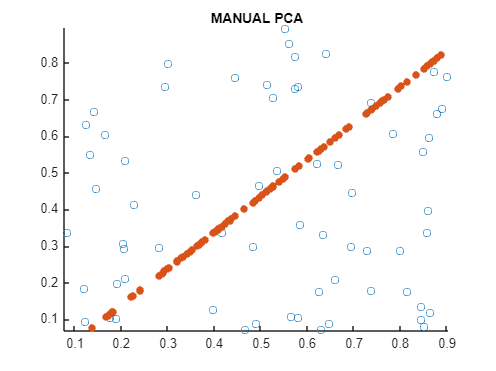


%plotting the original data and the principal components.
y = y .* std(data, 0, 1) + mean(data, 1);
scatter(data(:,1),data(:,2));
hold on
title('MANUAL PCA')
scatter(y(:,1),y(:,2),"filled")
hold off

**USING MATLAB's PCA FUNCTION**

[coeff, score, ~, ~, explained, mu] = pca(x_std)

coeff =     0.7071    0.7071
    0.7071   -0.7071


score =     1.0228    0.5315
    1.0403   -0.8426
    0.7092    1.2139
    0.3961    0.4379
   -0.7940    1.0957
    0.0395    1.3497
    1.3336    0.3530
    0.8077    1.3928
   -0.1642   -2.2565
    0.0175    1.6057


explained =    55.0113
   44.9887


mu = 1.0e-15 *

   -0.2531    0.1155


% Project the data onto the first principal component
pc1_projection = score(:, 1)

pc1_projection =     1.0228
    1.0403
    0.7092
    0.3961
   -0.7940
    0.0395
    1.3336
    0.8077
   -0.1642
    0.0175


pc2_projection =     0.5315
   -0.8426
    1.2139
    0.4379
    1.0957
    1.3497
    0.3530
    1.3928
   -2.2565
    1.6057


% Reconstruct data from the first principal component
reconstructed_data_pca1 = pc1_projection * coeff(:, 1)' + mu

reconstructed_data_pca1 =     0.7232    0.7232
    0.7356    0.7356
    0.5015    0.5015
    0.2801    0.2801
   -0.5614   -0.5614
    0.0279    0.0279
    0.9430    0.9430
    0.5711    0.5711
   -0.1161   -0.1161
    0.0124    0.0124


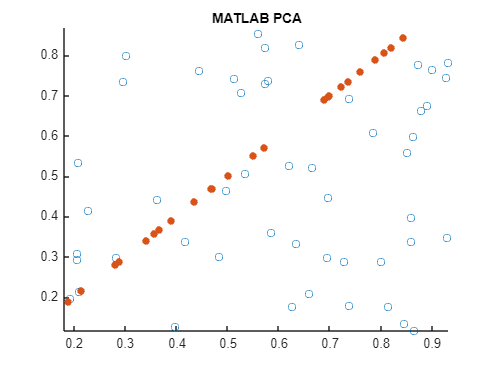

% Ploting both original and reconstructed data
scatter(data(:, 1), data(:, 2));
hold on;
xlim([0 1])
ylim([0 1])
title('MATLAB PCA')
scatter(reconstructed_data_pca1(:, 1), reconstructed_data_pca1(:, 2), 'filled');
hold off;


% Display variance explained by each principal component
disp('Variance explained by each component:');

Variance explained by each component:


disp(explained);

   55.0113
   44.9887

